# Homework 8

## Exam 2012, Problem 3: PSD Estimation

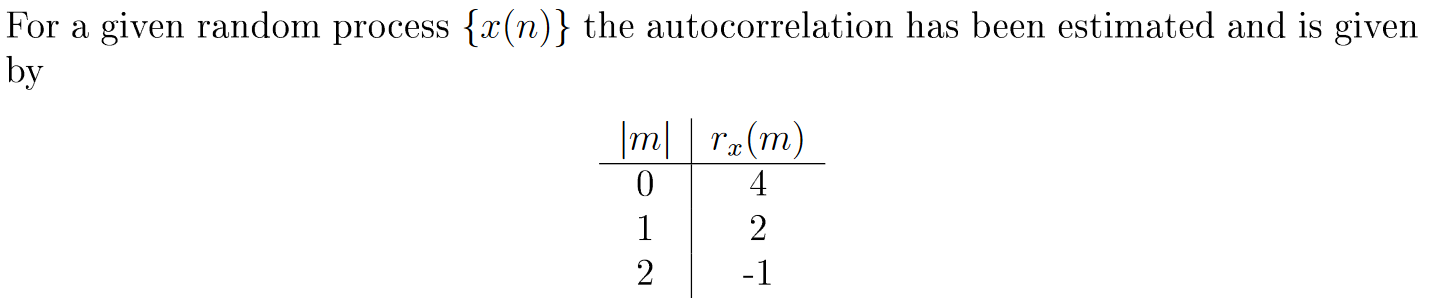

clear variables;

### 👀 1) Estimate PSD assuming sinusoidal white noise

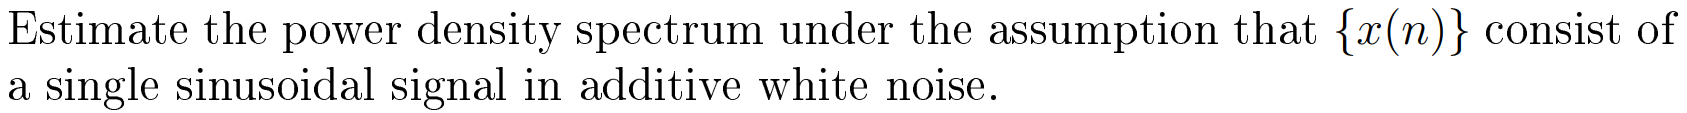

The Pisarenko method is used to estimate the power spectrum density of a random process. 

The method makes two assumptions:

- The signal $x\left(n\right)$ consists of $p$ sinusoids that has been corrupted by white noise.

- The autocorrelation matrix of size $\left(p+1\right)\times \left(p+1\right)$ is known or can be estimated

Given these assumptions, the Pisarenko method can recover the sinusoidal frequencies of the corrupted signal using the following steps:

***Step 1***: Compute the autocorrelation matrix ${\mathbf{R}}_{\mathrm{yy}}$

***Step 2:*** Find the eigenvector corresponding to the smallest minimum eigenvalue. The elements of this eigenvector is the parameters of the $\mathrm{ARMA}\left(2p,2p\right)$ model 

***Step 3:*** Find the frequencies $\left\lbrace \;f_i \;\right\rbrace$ of the sinusoids. This can be done by computing the roots of the polynomial $A\left(z\right)$ in (14.5.4). This polynomial has $2p$ poles on the unit circle which correspond to the frequencies of the system.

        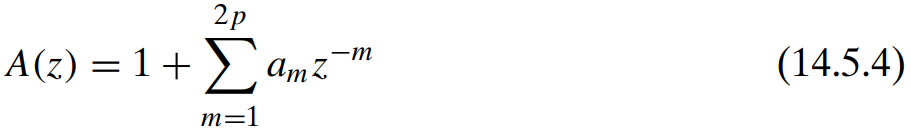

***Step 4*****:** Solve Eq. (14.5.11) for the signal powers $\left\lbrace P_i \right\rbrace$

        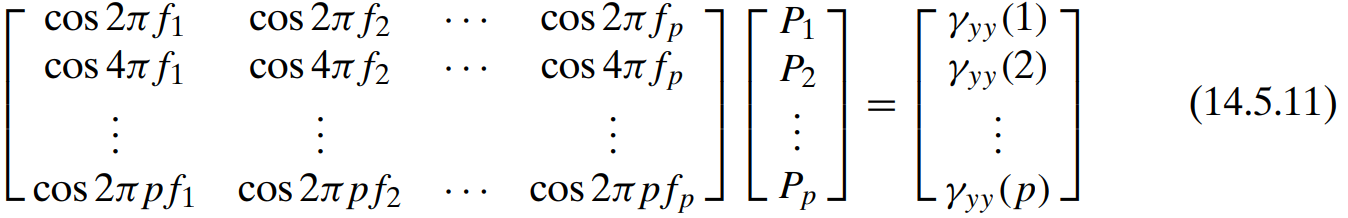

where 

- $\gamma_{\mathrm{yy}} \left(1\right),\gamma_{\mathrm{yy}} \left(2\right),\cdots ,\gamma_{\mathrm{yy}} \left(p\right)$ are the estimated autocorrelation values 

- $P_i =\frac{A_i^2 }{2}$ is the average power of the $i$th sinusoid and $A_i$ is the corresponding amplitude

***Step 5***: Estimate the amplitude $A_i =\sqrt{2P_i }$

These steps are coded up in the `pisarenko()` function (see at end of this document):

r_xx = [4, 2, -1];
[F, A, P, lambda_min] = pisarenko(r_xx, 1)

We can describe the signal as follows:

        
$$x\left(n\right)=2\ldotp 597\cdot \mathrm{cos}\left(2\pi \cdot 0\ldotp 149n+\phi \right)+w\left(n\right)$$


where $w\left(n\right)$ is white noise with variance $\sigma_w^2 =0\ldotp 6277$.

In ADSI Problem 4.4, we found that the autocorrelation of a real sinusoid given by $y\left(n\right)=A\;\mathrm{cos}\left(\omega n+\phi \right)$ where $A$ and $\omega$ are real constants and $\phi$ is a random variable with $\phi ~U\left(0,2\pi \right)$ is:

        
$$r_{\textrm{yy}} \left(\ell \right)=\frac{A^2 }{2}\mathrm{cos}\left(\omega \ell \right)$$


The autocorrelation function of white noise with variance $\sigma_w^2$ is given by:

        
$$r_{\mathrm{ww}} \left(\ell \right)=\sigma_w^2 \delta \left(\ell \right)$$


Using these results, we have the autocorrelation function of the signal:

        
$$r_{\mathrm{xx}} \left(\ell \right)=\frac{A^2 }{2}\mathrm{cos}\left(\omega \ell \right)+\sigma_w^2 \delta \left(\ell \right)$$


ell = 0:2;
(A^2/2) * cos(2*pi*F*ell) + lambda_min * (ell == 0)

**HELP: Is this correct? The given ACRS was [4, 2, -1]. Should we not get results close to this?**

The power spectral density is the Fourier transform the autocorrelation function:

        
$$S\left(\omega \right)=\frac{A^2 }{2}\pi \left\lbrack \delta \left(\omega -\omega_0 \right)+\delta \left(\omega +\omega_0 \right)\right\rbrack +\sigma_w^2$$


**HELP: Not sure if the Fourier transform is computed correct.**

Putting the values, we have:

        
$$S\left(\omega \right)=\frac{{\left(2\ldotp 597\right)}^2 }{2}\pi \left\lbrack \delta \left(\omega -2\pi \cdot 0\ldotp 149\right)+\delta \left(\omega +2\pi \cdot 0\ldotp 149\right)\right\rbrack +0\ldotp 6277$$


(A^2*pi)/2
2*pi*F

F = 0.1490

A = 2.5970

P = 3.3723

lambda_min = 0.6277

        
$$S\left(\omega \right)=10\ldotp 5943\left\lbrack \delta \left(\omega -0\ldotp 9359\right)+\delta \left(\omega +0\ldotp 9359\right)\right\rbrack +0\ldotp 6277$$


### 2) Estimate PSD assuming MA(2) process

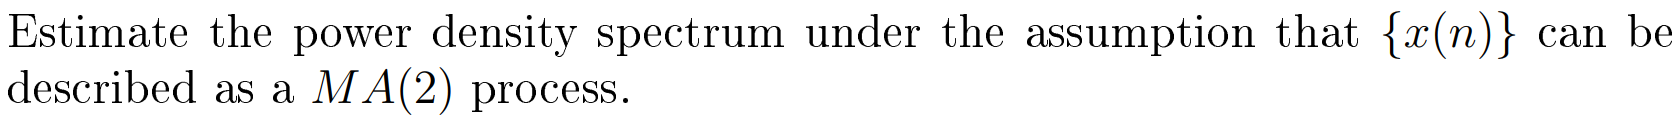

## Functions

function [F, A, P, lambda_min]=pisarenko(r_xx, p)
    % Estimates the frequencies and amplitudes using the Pisarenko method

ans =     4.0000    2.0000   -1.0000


    %  r_xx: autocorrelation sequence starting from zero. 
    %        The length of ACRS must be at least 2p+1.
    %  p: assumed number of sinusoids in the signal
    %  F: normalised frequencies of the sinuoids
    %  A: amplitudes of the sinuoids
    if numel(r_xx) < 2*p+1
        error(strcat('The length of ACRS must be at least ', int2str(2*p+1)));
    end
    
    % Compute the autocorrelation matrix

ans = 10.5943

    R_xx = toeplitz(r_xx(1:2*p+1));

ans = 0.9359

    
    % Perform the eigendecomposition
    [eigvecs, eigvals] = eigs(R_xx, size(R_xx, 1), 'smallestreal');
    
    eigvals = diag(eigvals);
    lambda_min = eigvals(1);
    
    % Find the eigenvector 'a' corresponding to the smallest eigenvalue.
    % The function eigs() sorts eigenvectors, so just pick the first column.
    a = eigvecs(:, 1);
    
    % Ensure that a_0 = 1 (this is by definition)
    a = a / a(1);
    
    % The elements of this eigenvector corresponds to the parameters
    % of an ARMA(2p, 2p) model: a_0, a_1, ..., a_2p where p: number of sinusoids
    % The polynomial A(z) in (14.5.4) has 2p poles on the unit circle.
    % Obtain the poles by finding the roots of the system.
    z = roots(a);
    
    % Estimate frequencies
    F = zeros(p, 1);
    for i = 1:p
        % The poles come in pairs. Each pair is complex conjugate
        % of one another. Only use one of them and find the absolute value.
        z_i = z(2*i);
        F(i) = abs(angle(z_i)) / (2*pi);
    end
    
    % Build the matrix of cosines
    C = zeros(p);
    for i = 1:p
        for j = 1:p
            C(i, j) = cos(i * 2*pi * F(j));
        end
    end
    
    % Start the ACRS from the second element according to equation (14.5.11)
    gamma = r_xx(2:p+1);
    
    % Solve equation (14.5.11) for P
    P = C\gamma; % Same as `inv(C)*gamma` but faster and more accurate
    
    % Since P=A^2/2, we can compute the amplitude A=sqrt(2*P)
    A = sqrt(2 * P);
end